%% update on 6th Sept 2024
close all; clc;
file_path = 'WP_50k_from2000_beforeMS.csv';
% file_path = 'WP_50k_afterMS.csv';

disp(['CSV file name: ', file_path]);

CSV file name: WP_50k_from2000_beforeMS.csv


dataTable = readtable(file_path);
write_matrix = table2array(dataTable);

startdate=datetime('2000-01-01 00:00:00');%year,month,day,hour,minute,second
% startdate=datetime('1995-01-01 00:00:00');%year,month,day,hour,minute,second
%startdate=datetime('2021-09-21 23:15:53');%year,month,day,hour,minute,second
% startdate= datetime('2021-09-21 23:15:53') + days(2);%year,month,day,hour,minute,second
enddate=datetime('2031-01-01 00:00:00');%year,month,day,hour,minute,second
% enddate = startdate + years(1);
% 

currentDateTime = datetime(write_matrix(:, [3, 4, 5, 8, 9, 10]));
index = find(currentDateTime >= startdate & currentDateTime < enddate);


write_matrix = write_matrix(index,:);


%% Convert Ml to Mw
Ml = write_matrix(:,6);


index = find(Ml >=0);
write_matrix = write_matrix(index,:);

%% GR law calculation
magnitudeVector=write_matrix(:,6);
%divide in bins
mag_range=min(magnitudeVector):0.1:7;
[number,bin]= hist(magnitudeVector,mag_range'); % calculate the number per bin
mag_count=[bin,number'];
for i=1:length(mag_count)
    mag_count(i,3)=sum(mag_count(i:end,2));
end


M = 0:0.1:max(Ml);
a = 2.932;
b = 0.9;
num1 = power(10,a-b*M);

semilogy(M, num1, 'LineWidth', 1.2, 'Color', 'blue');

hold on;
a = 3.29;
b = 0.58;
num2 = power(10,a-b*M);
semilogy(M,num2,'LineWidth',1.2,'Color', 'red');

num3 = (num1+num2)/2;
a = log10((power(10,3.29)+power(10,2.932))/2);
b = (a-log10(num3(2)))/M(2);
disp(['Synthetic Background Seismicity I: b = ', num2str(b), ', a = ', num2str(a)]);

Synthetic Background Seismicity I: b = 0.67508, a = 3.1469


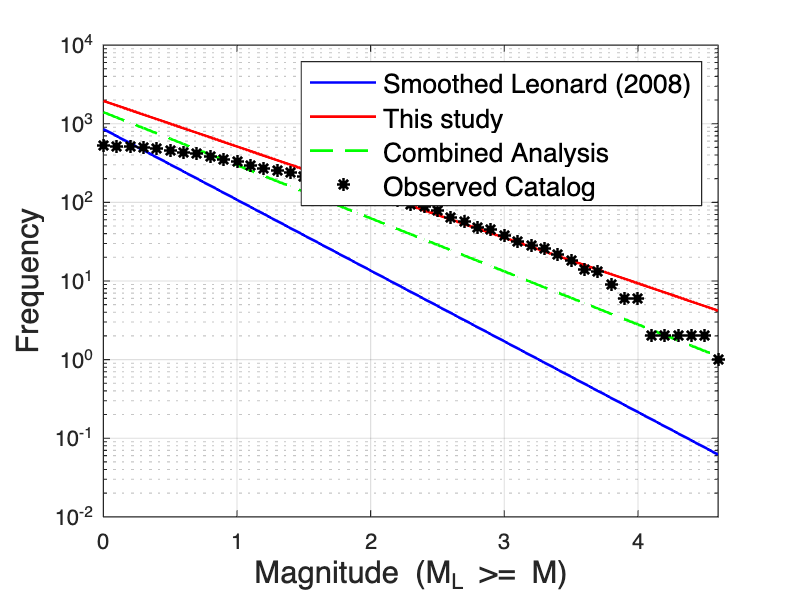

num = power(10,a-b*M);
semilogy(M,num,'--','LineWidth',1.2,'Color', 'green');

semilogy(mag_count(:,1),mag_count(:,3),'k*','LineWidth',1.2);


legend({'Smoothed Leonard (2008)','This study','Combined Analysis','Observed Catalog'},'FontSize',12);
grid on;
xlim([0,max(Ml)]);
xlabel('Magnitude (M_L >= M)','FontSize',14);
ylabel('Frequency','FontSize',14);